clc
clear all

## Reading run file

Here you can import .csv file from the datasets. you should pick as type COLUMN VECTORS. For Cerberus you should add to the data the altitude and the heartrate because Diego likes it. 

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["timestamp", "altitude", "heart_rate", "cadence", "distance", "speed", "power"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "timestamp", "InputFormat", "yyyy-MM-dd'T'HH:mm:ss");

% Import the data
Diego_15_09_2023_AM_22 = readtable("/home/lorenzo/Documents/Data-Analysis-Policumbent/BM_23/Cerberus/Diego_15_09_2023_AM_2.csv", opts);

% Convert to output type
timestamp = Diego_15_09_2023_AM_22.timestamp;
altitude = Diego_15_09_2023_AM_22.altitude;
heart_rate = Diego_15_09_2023_AM_22.heart_rate;
cadence = Diego_15_09_2023_AM_22.cadence;
distance = Diego_15_09_2023_AM_22.distance;
speed = Diego_15_09_2023_AM_22.speed;
power = Diego_15_09_2023_AM_22.power;

% Clear temporary variables
clear Diego_15_09_2023_AM_22

% Clear temporary variables
clear opts

% Display results
timestamp, altitude, heart_rate, cadence, distance, speed, power

timestamp = 448×1 datetime array
   2023-09-15T09:57:52
   2023-09-15T09:57:53
   2023-09-15T09:57:54
   2023-09-15T09:57:55
   2023-09-15T09:57:56
   2023-09-15T09:57:57
   2023-09-15T09:57:58
   2023-09-15T09:57:59
   2023-09-15T09:58:00
   2023-09-15T09:58:01
   2023-09-15T09:58:02
   2023-09-15T09:58:03
   2023-09-15T09:58:04
   2023-09-15T09:58:05
   2023-09-15T09:58:06
   2023-09-15T09:58:07
   2023-09-15T09:58:08
   2023-09-15T09:58:09
   2023-09-15T09:58:10
   2023-09-15T09:58:11
   2023-09-15T09:58:12
   2023-09-15T09:58:13
   2023-09-15T09:58:14
   2023-09-15T09:58:15
   2023-09-15T09:58:16
   2023-09-15T09:58:17
   2023-09-15T09:58:18
   2023-09-15T09:58:19
   2023-09-15T09:58:20
   2023-09-15T09:58:21


altitude = 1.0e+03 *

    1.4670
    1.4670
    1.4670
    1.4670
    1.4670
    1.4674
    1.4674
    1.4676
    1.4678
    1.4678


heart_rate =    118
   122
   125
   125
   128
   131
   134
   136
   136
   138


cadence =     48
    50
    50
    52
    52
    54
    54
    58
    59
    59


distance = 1.0e+03 *

    0.0215
    0.0280
    0.0347
    0.0418
    0.0488
    0.0566
    0.0647
    0.0724
    0.0800
    0.0880


speed =    22.2370
   23.1440
   24.3180
   24.9910
   25.4950
   26.3020
   27.0400
   27.3420
   27.9470
   28.5840


power =    175
   158
   171
   171
   170
   170
   151
   151
   170
   184


time = 1:size(power);   % We have a sample every second, easy as it is.

## Data visualization

Just data plotting, remember to add altitude and heartrate for Diego because he likes it.

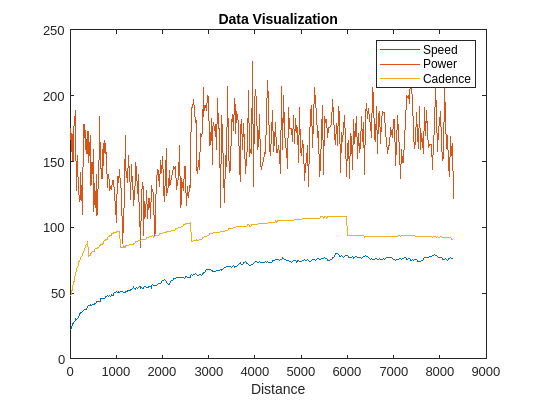

plot(distance,speed,distance,power,distance,cadence);
legend("Speed","Power","Cadence");
title("Data Visualization");
xlabel("Distance");

avg_power = mean(power)

avg_power = 157.3460

avg_power_last_km = mean(power(288:end))

avg_power_last_km = 171.2236

## System modeling

sys = [speed,power];
nx = 1;
model = n4sid(sys,nx);

## Simulation

As seen by the real data, the best speed is reached by using an incremental linear power input. Down here you can modify the values of each line of power.

k = size(power,1);
a = 0.829;
b = 1.15;
ScatterFactor = a+(b-a)*rand(k,1);

Here you have to choose the slope of each segment of the power line. The standard coefficients usually fit well but the choice is up to you.

m1 = 0.7;
m2 = 1.1;
m3 = 0.85;

Here you can choose the average power input for each segment. The lenght of the ScatterFactor in each segment is measured is seconds and it corresponds to the time each power input has to be maintained by the rider. You can choose the lenght of each segment by modifying t1, t2, t3, t4. 

**The sum of t1, t2, t3, t4 must be k, whitch is the lengh of the training dataset, the s variables do just so.**

t1 =  ; s2 = k-t1;
t2 = 0; s3 = k-t1-t2;
t3 = 0; s4 = k-t1-t2-t3;
t4 = 0; 
x1 = ScatterFactor(1:t1)*130;
x2 = ScatterFactor(1:t2)*190;
x3 = ScatterFactor(1:t3)*225;
x4 = ScatterFactor(1:t4)*250;
y1 = m1*x1;
y2 = m2*x2;
y3 = m2*x3;
y4 = m3*x4;

Just vector concatenation, simulation and plotting.

Sim_power_lin = [y1',y2',y3',y4']';
simSpeed = sim(model,Sim_power_lin);
max_speed = max(simSpeed)

max_speed = 42.8154

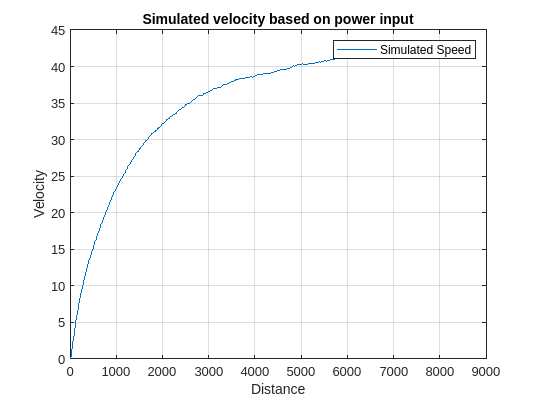


plot(distance, simSpeed);
title("Simulated velocity based on power input");
legend("Simulated Speed");
xlabel("Distance");
ylabel("Velocity");
grid on;